clear;
clc;

L_1 = 10;   %Distance between leak and support-1 in m
L_2 = 10;   %Distance between leak and support-2 in m

%Assumption: Orifice leak
R_leak = 0.008; %Radius of leak in m
A_leak = pi*R_leak*R_leak;  %Area of leak in m^2
A = A_leak;
% open("leak_simulation.slx");

out = sim("leak_simulation.slx");

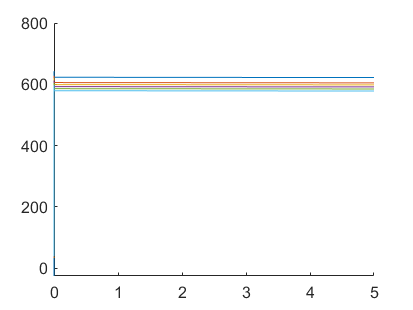

Q_1 = out.Q_1;
hold on
labels_Q=["Q input"];
plot(Q_1);
for i=1:5
    A = A_leak*i;
    out = sim("leak_simulation.slx");
    Q_2 = out.Q_2;
    plot(Q_2);
    labels_Q = [labels_Q "Q"+string(i)+" A_L"+string(i)+"="+A*10000+"cm^2"];
end

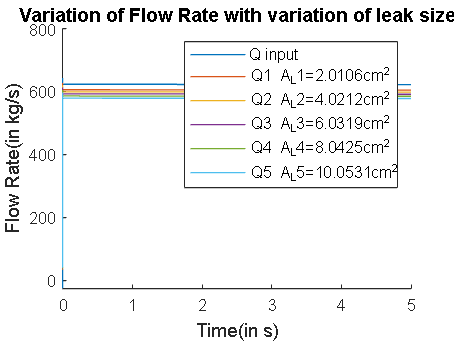

legend(labels_Q);
title('Variation of Flow Rate with variation of leak size');
xlabel('Time(in s)');
ylabel('Flow Rate(in kg/s)');

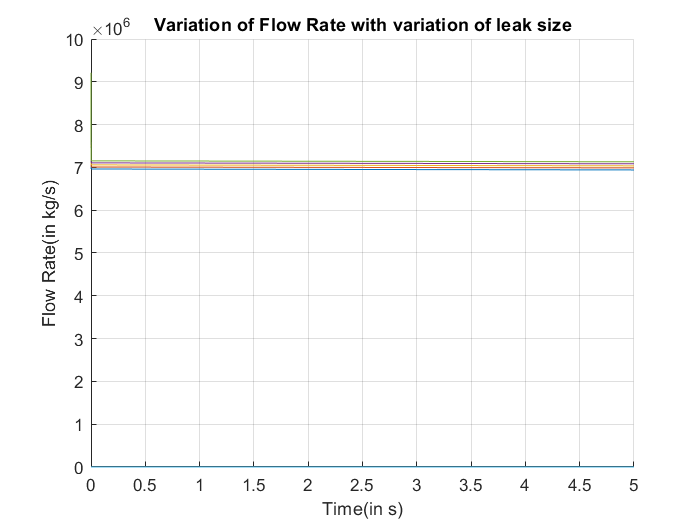


hold off;
legend("hide"); 
A = A_leak;
hold on;
out = sim("leak_simulation.slx");
P_diff=out.P_diff;
labels_P=[];
plot(P_diff)
for i=1:5
    A = A_leak*i;
    out = sim("leak_simulation.slx");
    P_diff = out.P_diff;
    plot(P_diff);
    labels_P = [labels_P "P"+string(i)+" A_L"+string(i)+"="+A*10000+"cm^2"];
end

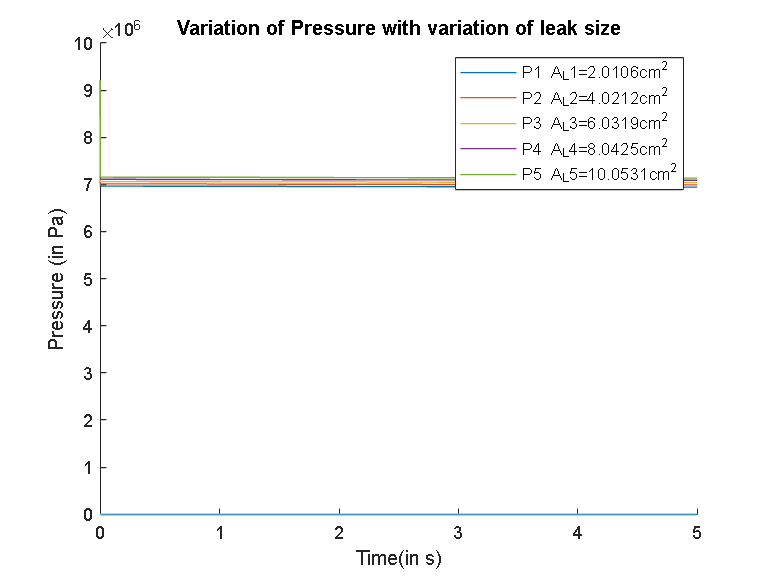

legend(labels_P);
title('Variation of Pressure with variation of leak size');
xlabel('Time(in s)');
ylabel('Pressure (in Pa)');